% zad 4.1
p = [1, 0, 0]';
alpha = pi/2;
beta = pi/2;
gamma = pi/2;
t = [1, 0, 0]';

func1(p, alpha, beta, gamma, t)

ans =     1.0000
    0.0000
   -1.0000


% zad 4.5
modelName = 'model'

modelName = 'model'

load_system(modelName);
zad2_params();
zad3_params();

simOut = sim('model')

simOut =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                quality: [56x1 double] 
                      t: [56x1 double] 
                   tout: [56x1 double] 
                      y: [56x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


quality = simOut.quality(end)

quality = 1.0901

% x = [K, alpha, beta]';
x0 = [0.5, 0.5, 1]';
fun = @(x) optim(x);
x = fminsearch(fun,x0)

x =     0.6167
   -0.9036
    3.2657


simOut = sim('model');
quality = simOut.quality(end)

quality = 0.3106

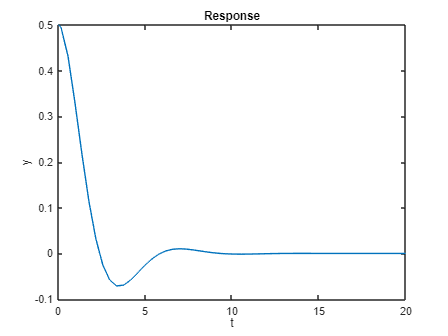

y = simOut.y;
t = simOut.t;
plot(t, y);
title("Response");
xlabel('t');
ylabel('y');

function y = optim(x)
    % update parametrów
    K = x(1,1);
    alpha = x(2,1);
    beta = x(3,1);
    assignin('base', "K", K);
    assignin('base', 'alpha', alpha);
    assignin('base', 'beta', beta);
    % symulacja modelu
    simOut = sim('model');
    y = simOut.quality(end);
end